# Filtro de media movil

Un filtro de media móvil es una técnica utilizada para suavizar una serie de datos (como precios de acciones, temperaturas, etc.) con el fin de eliminar el ruido y mostrar una tendencia más clara. Funciona calculando el promedio de un conjunto de datos dentro de una ventana deslizante.

% Generar una señal de 500 muestras con una tendencia lineal y ruido aleatorio
N = 500; % Número de muestras
n = 0:N-1; % Eje temporal
senal_original = 20 + 0.05 * n; % Tendencia lineal
%senal_original = 3*cos(2*pi*0.01*n) - 2*sin(2*pi*0.05*n);
ruido = randn(1, N); % Ruido aleatorio
senal_con_ruido = senal_original + ruido;

Definicion de la ventana y valores de media movil

% Número de muestras para la media móvil
ventana = 5;

% Inicializar el vector de medias móviles
media_movil = zeros(1, N);

Aplicacion del filtro de media movil a la señal de prueba

for i = ventana:N
    media_movil(i) = mean(senal_con_ruido(i-ventana+1:i)); % Promedio dentro de la ventana
end

Generando las figuras de las señales

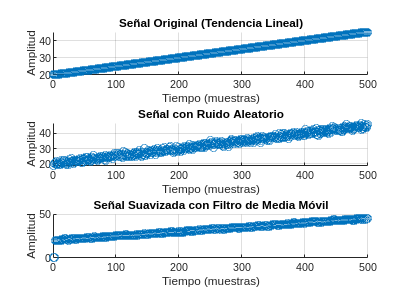

figure()

% Graficar la señal original (tendencia)
subplot(3,1,1);
scatter(n, senal_original);
title('Señal Original (Tendencia Lineal)');
xlabel('Tiempo (muestras)');
ylabel('Amplitud');
grid on;

% Graficar la señal ruidosa
subplot(3,1,2);
scatter(n, senal_con_ruido);
title('Señal con Ruido Aleatorio');
xlabel('Tiempo (muestras)');
ylabel('Amplitud');
grid on;

% Graficar la señal suavizada (media móvil)
subplot(3,1,3);
scatter(n, media_movil);
title('Señal Suavizada con Filtro de Media Móvil');
xlabel('Tiempo (muestras)');
ylabel('Amplitud');
grid on;

## Mediciones sobre las señales

Se aplicaran mediciones para verificar el efecto del filtro de media movil

Primero entre la señal original y la señal ruidosa

% Error cuadratico medio (MSE)
Err1 = (1/(N-ventana)) *(sum( (senal_original(ventana:end) - senal_con_ruido(ventana:end)) .^ 2))

Err1 = 0.9592

Ahora entre la señal original y la señal suavizada

% Error cuadratico medio (MSE)
Err2 = (1/(N-ventana)) *(sum( (senal_original(ventana:end) - media_movil(ventana:end)) .^ 2))

Err2 = 0.2157